# Calibrating the Estimated Local Volatility Function (LVF) Model from Market Prices of the European Call Option

By: Samuel Reano

A typical practice in finance is to estimate an option pricing model from market prices of options that are traded frequently (in other words, liquid options). The calibrated model can be used to hedge liquid options or price and hedge other (illiquid) exotic options on the same underlying. In this project, we will consider the calibration of a local volatility function (LVF) model in practice.

You will need the following MATLAB function files:

- Eur_Call_LVF_MC.m

- Eur_Call_LVF_FD.m

- myfun.m

## Local Volatility Function Model

The Local Volatility Function model assumes the stock price as 


$$dS = rS dt + \sigma(S,t) S dW_t,$$


where $\sigma(S,t) = \max \left \lbrace 0, x_1 + x_2S + x_3 S^2  \right \rbrace.$ The European call option value is the solution of the partial differential equation 


$$V_\tau - \frac{\sigma^2(S,\tau)}{2} S^2 V_{SS} - rSV_S + rV = 0,$$


where $\tau = T - t$ is the time to maturity.

## Comparing the Monte Carlo Method and the Explicit Finite Difference Method

The following chunk of code computes the results from the Monte Carlo Method and from the explicit finite difference method. 

%% The Monte Carlo Method

%Parameters
S0 = 1;
K = 1;
T = 0.25;
r = 0.03;
x = [0.2 0.001 0.003];
M = 10000;
N = 100;

%Calling the MATLAB function file for Monte Carlo
V = Eur_Call_LVF_MC(S0,K,T,r,x,M,N)

V = 5.0331e-04


%% The explicit finite difference method

%Parameter
Smax = 3;

%Calling the MATLAB function file for explicit finite difference
V0 = Eur_Call_LVF_FD(S0,K,T,r,x,Smax,30,N)

V0 = 0.0381

Whenever you run this chunk of code, the value of V0 remains the same whereas the value of V changes. This is due to the randomness behaviour of stochastic differential equations and the MATLAB function *randn*. 

## The Calibration Problem and its Challenges

Assume that the initial market prices $V_{0}^{\text{mkt}}(K_j,T_j), j=1, 2, ..., m,$ are available; here $(K_j,T_j)$ denotes the strike and expiry of the *j*-th option. 

Assume that $V_0(K_j,T_j;x)$ denotes the initial value of an option with strike $K_j$ and $T_j$ under the quadratic LVF model described by the set of parameters $x = (x_1, x_2, x_3)$.

The model which best fits the market option prices can be estimated by solving the following nonlinear least squares problem


$$\min_{x \in \mathbb{R}^n} \frac{1}{2} \sum_{j=1}^{m} \left( V_0(K_j, T_j; x) - V_{0}^{\text{mkt}}(K_j, T_j) \right)^2. $$


Let $F(x)$ denote the vector of model option value errors from the market prices:


$$F\left(x\right)=\left\lbrack \begin{array}{c}
V_0 \left(K_1 ,T_1 ;x\right)-V_0^{\mathrm{mkt}} \left(K_{1,} T_1 \right)\\
\vdots \\
V_0 \left(K_m ,T_m ;x\right)-V_0^{\mathrm{mkt}} \left(K_m ,T_m \right)
\end{array}\right\rbrack$$


Vector $F(x): \mathbb{R}^n \longrightarrow \mathbb{R}^m$ is nonlinear function of the model parameter $x \in\mathbb{R}^n$ and the nonlinear least squares problem is equivalently formulated as 

$\min_{x \in \mathbb{R}^n} \left(f(x) = \frac{1}{2} ||F(x)||_{2}^{2} \right)$.

This nonlinear least squares problem can be solved by using the Levenberg-Marquardt optimization problem. 

% starting points
x01 = [0.2;0.0;0.0];
x02 = [0.2;0.1;0.01];

% lsqnonlin function to obtain non-linear least squares data fitting
% Specifies inputs contain derivative information
options = optimoptions('lsqnonlin','SpecifyObjectiveGradient',true);

% Levenberg-Marquardt Method
options.Algorithm = 'levenberg-marquardt';

% Output is displayed for each iteration
options.Display = 'iter';

[cx1,resnorm1] = lsqnonlin(@myfun,x01,[],[],options);


                                        First-order                     Norm of
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           1         0.311733            3.13         0.01
     1           2         0.311423            3.13        0.001      0.0575503
     2          14                                                  5.4052e-08

Local minimum possible.
lsqnonlin stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


[cx2,resnorm2] = lsqnonlin(@myfun,x02,[],[],options);


                                        First-order                     Norm of
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           1         0.312056            3.14         0.01
     1           2         0.310945            3.14        0.001      0.0575696
     2          14         0.310417            3.14        1e+08      5.414e-08

Local minimum possible.
lsqnonlin stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


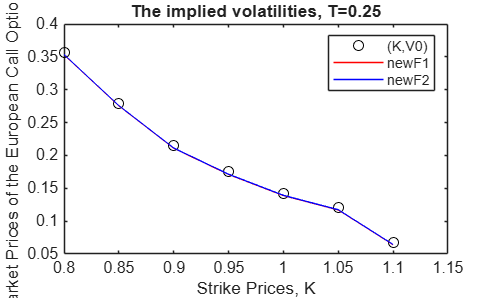


% Creating the plot
K = [0.80 0.85 0.90 0.95 1.00 1.05 1.10]; % a vector of strike prices
V0 = [0.3570 0.2792 0.2146 0.1747 0.1425 0.1206 0.0676]; % a vector of initial market European call option prices

% F(x) and the Jacobian matrices
[F1,J1] = myfun(cx1);
[F2,J2] = myfun(cx2);

% f(x)
fun1 = 0.5*(norm(F1))^2;
fun2 = 0.5*(norm(F2))^2;

newF1 = abs(F1); % take the absolute value of all elements in F1 that are negative
newF2 = abs(F2); % take the absolute value of all elements in F2 that are negative
plot(K,V0,'ko',K,newF1,'r-',K,newF2,'b-')
xlabel({'Strike Prices, K'});
ylabel({'Market Prices of the European Call Option, V0'});
title({'The implied volatilities, T=0.25'});
legend('(K,V0)','newF1','newF2');

fprintf('Value of fun1: %d, Value of fun2: %d\n',fun1,fun2)

Value of fun1: 1.556962e-01, Value of fun2: 1.561704e-01


The values of fun1 and fun2 tells us how close the regression is to the plotted points in terms of the distance between the plotted points and the curves themselves. We conclude that we are successful in solving the calibration problem.